# 仿真数据后处理

## 读取数据

clear;
clc;
path1="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_SA_U4";
path2="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.03_200_SA_U4";
path3="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.06_200_SA_U4";
% path4="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.06_200_turbulent_SA";
% path5="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_turbulent_SA";
% path6="C:\Users\admin\Desktop\pipeflow\pipeflow_L2200D8_ds0.01_200_turbulent_SA";
[data11,head11,all11]=xlsread(strcat(path1,"\z=1.5.csv"));
[data12,head12,all12]=xlsread(strcat(path1,"\z=0.001.csv"));
[data13,head13,all13]=xlsread(strcat(path1,"\xy=0.csv"));
[data21,head21,all21]=xlsread(strcat(path1,"\z=1.5.csv"));
[data22,head22,all22]=xlsread(strcat(path1,"\z=0.001.csv"));
[data23,head23,all23]=xlsread(strcat(path1,"\xy=0.csv"));
[data31,head31,all31]=xlsread(strcat(path1,"\z=1.5.csv"));
[data32,head32,all32]=xlsread(strcat(path1,"\z=0.001.csv"));
[data33,head33,all33]=xlsread(strcat(path1,"\xy=0.csv"));

#### 剖面数据

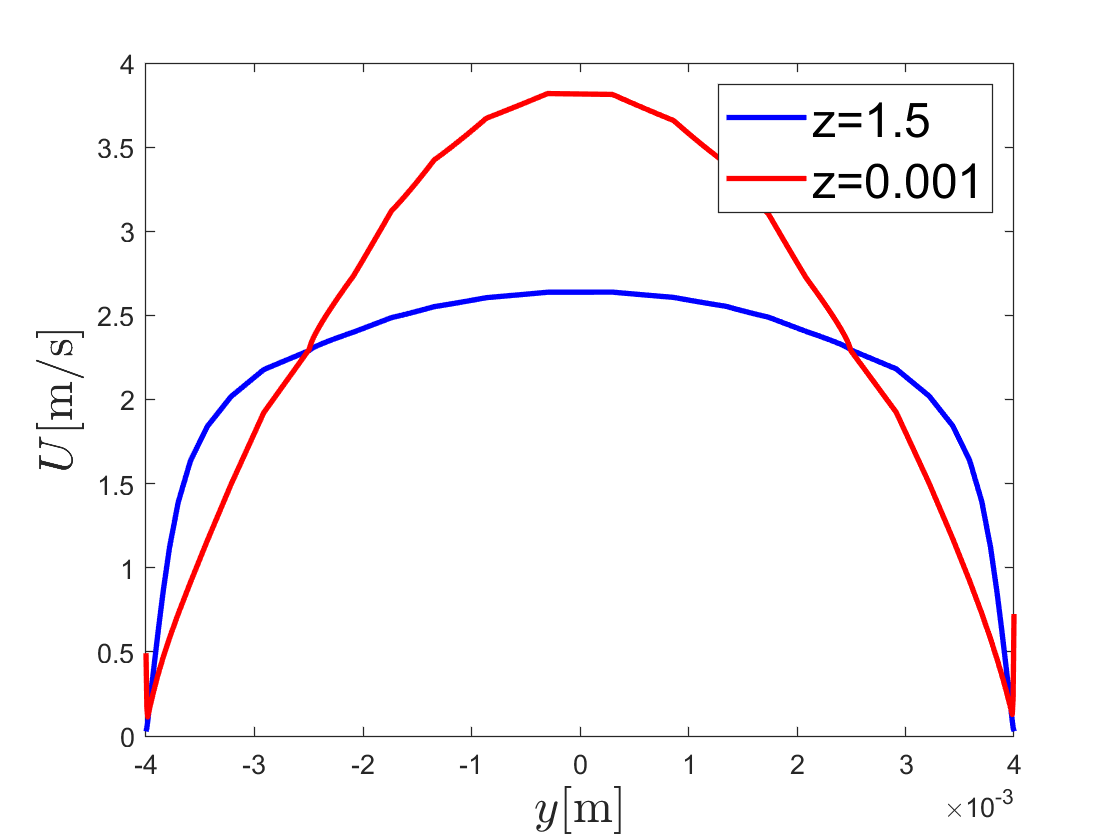

% xyz=data(:,1:3);
% Uxyz=data(:,5:7);
% UMag=data(:,8);
% xyz1=data1(:,1:3);
% Uxyz1=data1(:,5:7);
% UMag1=data1(:,8);

figure
plot(data11(:,2),data11(:,8),'-b','LineWidth',2);hold on;
plot(data12(:,2),data12(:,8),'-r','LineWidth',2);
% ti=title("Velocity Profile");
% ti.FontSize=18;
lg=legend("z=1.5","z=0.001");
lg.FontSize=18;
xlabel('$y$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$U$[m/s]','interpreter','latex', 'FontSize', 18);

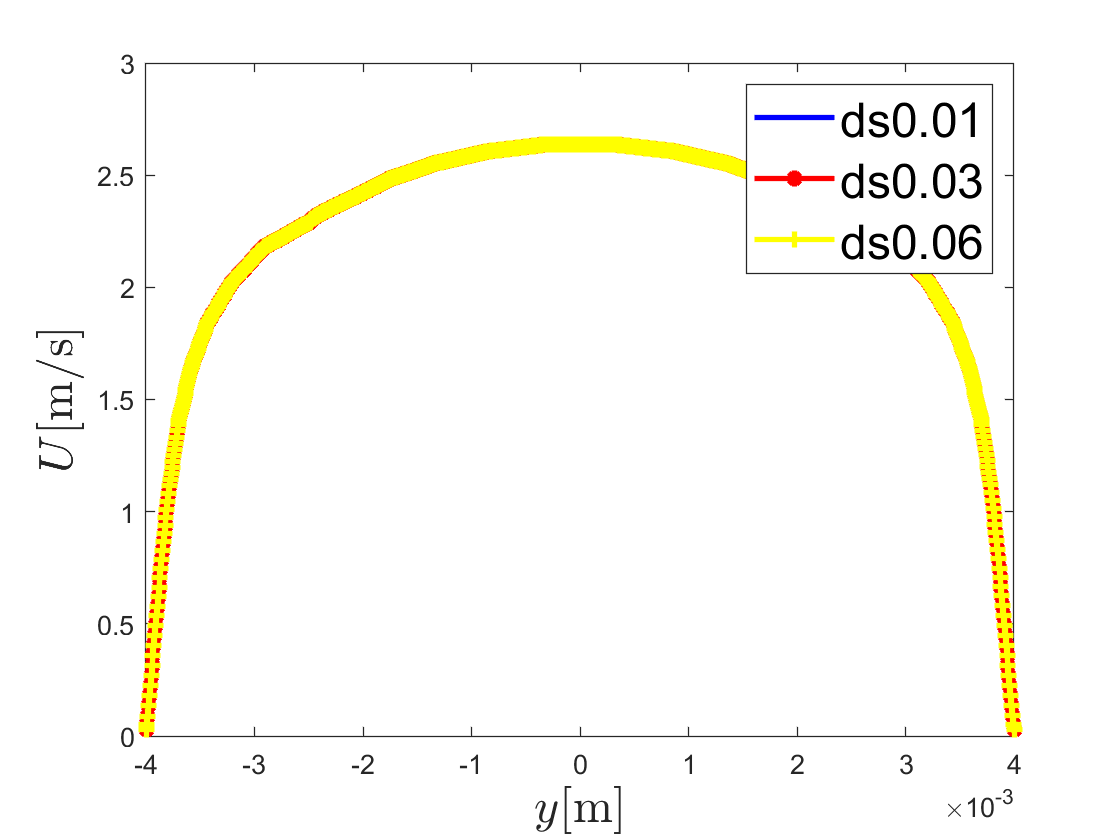


plotf(data11(:,2),data11(:,8),data21(:,2),data21(:,8),data31(:,2),data31(:,8),'$y$[m]','$U$[m/s]');

#### 压强数据

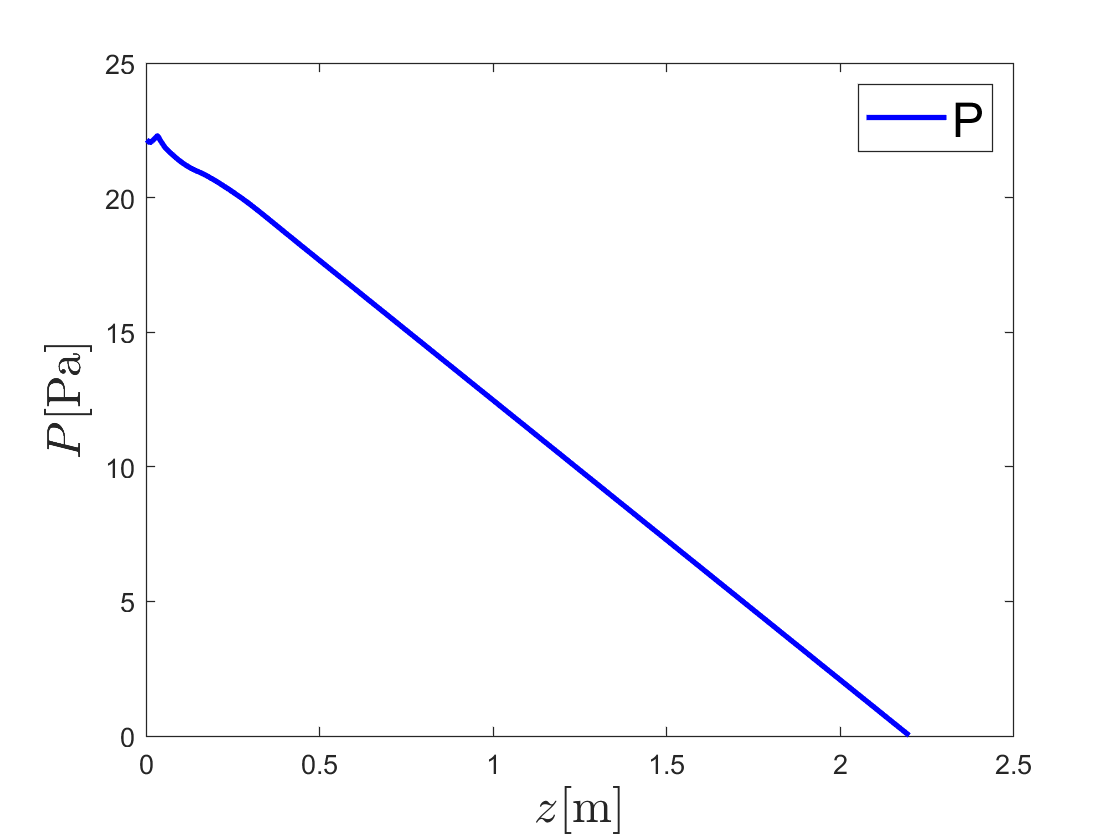


% xyz=data(:,1:3);
% Uxyz=data(:,5:7);
% UMag=data(:,8);
figure
plot(data13(2:end,3),data13(2:end,12),'-b','LineWidth',2);
lg=legend("P");
lg.FontSize=18;
xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
ylabel('$P$[Pa]','interpreter','latex', 'FontSize', 18);

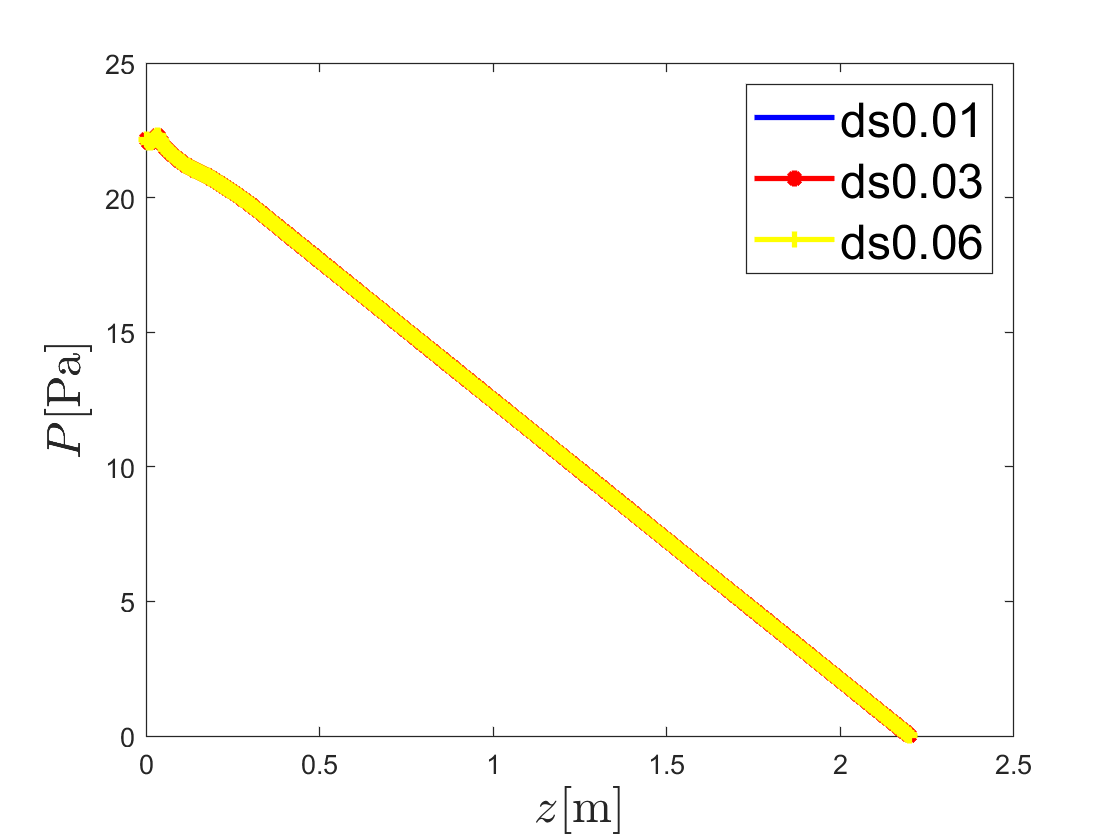


plotf(data13(2:end,3),data13(2:end,12),data23(2:end,3),data23(2:end,12),data33(2:end,3),data13(2:end,12),'$z$[m]','$P$[Pa]');

#### 根据压强计算摩擦因子


Um=2;
L=1;
d=0.008;
nu=3.75e-6;
Re=Um*d/nu;
lambda1=64/Re;
lambda2=0.3164/(Re^(0.25));
lambda(1)=(data13(365,12)-data13(820,12))/(0.5*Um^2*L/d);
lambda(2)=(data23(365,12)-data23(820,12))/(0.5*Um^2*L/d);
lambda(3)=(data33(365,12)-data33(820,12))/(0.5*Um^2*L/d);


#### 切应力

% [data,head,all]=xlsread(strcat(path1,"\x=-0.004.csv"));
% xyz=data(:,1:3);
% Uxyz=data(:,5:7);
% UMag=data(:,8);
% wallshear=data(:,15:18);
% figure
% plot(xyz(365:820,3),wallshear(365:820,1),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,2),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,3),'-b','LineWidth',2);hold on;
% plot(xyz(365:820,3),wallshear(365:820,4),'-b','LineWidth',2);
% lg=legend("wallshear1","wallshear2","wallshear3","wallshear4");
% lg.FontSize=18;
% xlabel('$z$[m]','interpreter','latex', 'FontSize', 18);
% ylabel('wallshear[Pa]', 'FontSize', 18);
